# Taller 11

#### Julian David Porras Morales

#### 1/10/2023

El objetivo de este taller es resolver numéricamente, por el método numérico de Runge-Kutta la ecuación de estado de un modelo epidemiológico SIRV, en donde se grafiquen los resultados variando parámetros para conocer el comportamiento epidemiológico de un virus dependiendo las distintas variables que lo afectan.

### 1

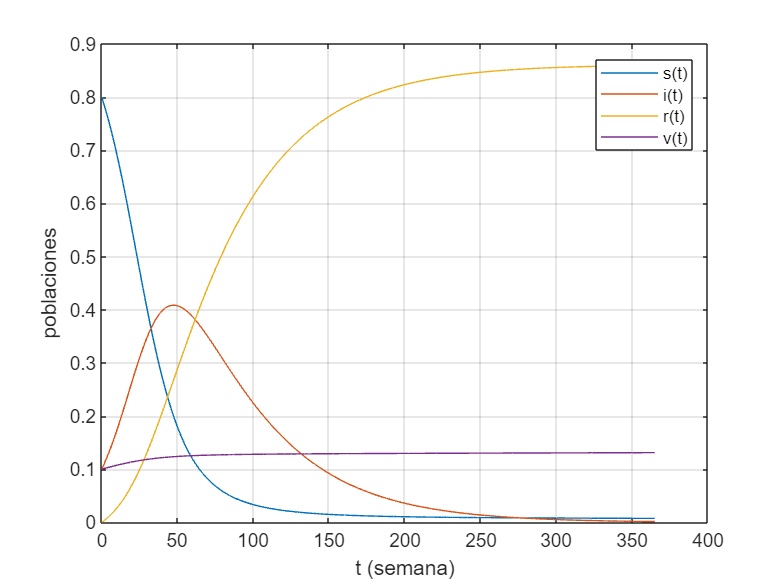

syms s(t) i(t) r(t) v(t)

%Parametros
beta = 0.1; gamma = 0.02; delta = 0.001;

%Ecuaciones
f1 = -beta*s*i - delta*s;
f2 = beta*s*i - gamma*i;
f3 = gamma*i;
f4 = delta*s;
f = odeFunction([f1 f2 f3 f4],[s i r v]);

%Metodos numericos
h = 0.1;
tmin = 0;
tmax = 365;
tspam = tmin:h:tmax;

%Condociones iniciales
ci = [0.8 0.1 0 0.1];

%Solucion metodo numerico
[t1,X1] = ode45(f,tspam,ci);
plot(t1,X1)
xlabel('t (semana)')
ylabel('poblaciones')
grid on
legend({'s(t)','i(t)','r(t)','v(t)'})

#### Calculo numerico cambiando v(0)

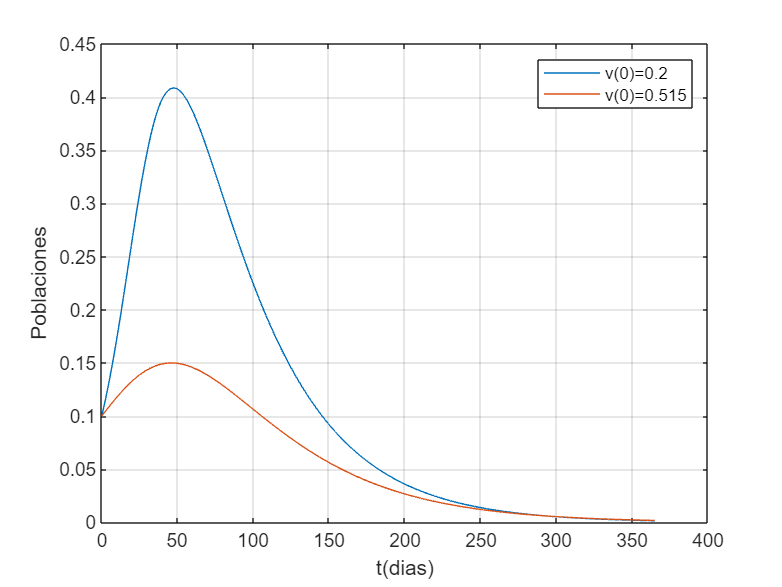

v0 = 0.515;
ci = [0.9-v0 0.1 0 v0];
[t2,Sol2] = ode45(f,tspam,ci);
I_sol2= Sol2(:,2);

plot(t1,X1(:,2),t2,I_sol2)
xlabel('t(dias)')
ylabel('Poblaciones')
grid on
legend({'v(0)=0.2',['v(0)=' num2str(v0)]})

La vaunacion hace que la cantidad de infectados se redusca, y esto se puede apreciar en las graficas, ya que entre mayor sea el numero de la poblacion inicial vacunada menor va a ser el numero de personas infectadas y estas van a reducirce en un menor tiempo.

Para el caso plateado en el que a poblacion infectada alcance un pico maximo de 0.15 y teniendo en cuenta que la poblacion inicial infectada es de 0.1, seria necesario que la poblacio inicial que este vacunada sea de aproximadamente 0.515.

#### 2. Soluciones numericas con cambio de i(0)

Observa el efecto negativo al tener inicialmente una poblacion mayor de personas infectadas

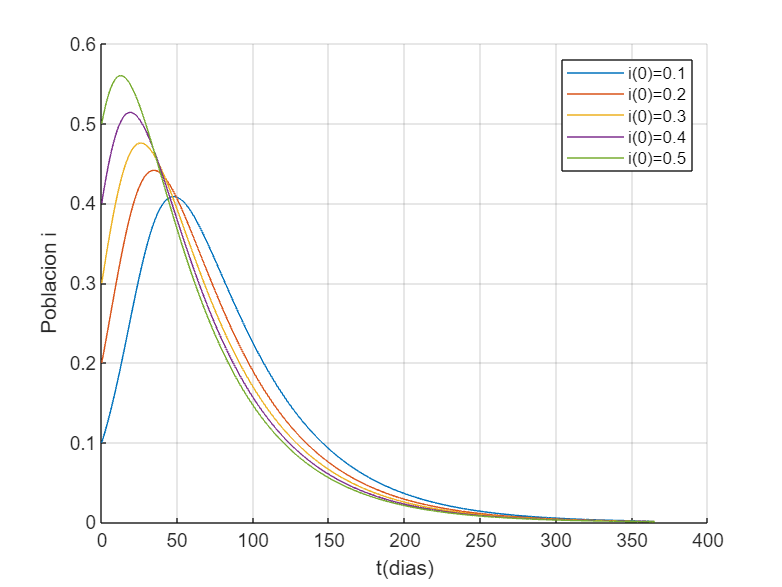

syms s(t) i(t) r(t) v(t)

%Parametros
beta = 0.1; gamma = 0.02; delta = 0.001;

%Ecuaciones
f1 = -beta*s*i - delta*s;
f2 = beta*s*i - gamma*i;
f3 = gamma*i;
f4 = delta*s;
f = odeFunction([f1 f2 f3 f4],[s i r v]);

%Metodo numerico
h = 0.1;
tmin = 0;
tmax = 365;
tspan = tmin:h:tmax;

%condiciones iniciales
MultipleCI = [0.8 0.1 0 0.1;
    0.7 0.2 0 0.1;
    0.6 0.3 0 0.1;
    0.5 0.4 0 0.1;
    0.4 0.5 0 0.1];

%Soli¿ucion metodo numerico
figure
for k = 1:length(MultipleCI)
    [t,x] = ode45(f,tspan,MultipleCI(k,:));
    hold on
    grid on
    plot (t,x(:,2))
    
end
legend({'i(0)=0.1','i(0)=0.2','i(0)=0.3','i(0)=0.4','i(0)=0.5'})
xlabel('t(dias)')
ylabel('Poblacion i')

Se puede observar que al tener una mayor población inicial infectada esta alcanza un pico mucho más alto y rápido, pero también este tiene un decremento más rápido que en donde la población inicial más infectada es la que más rápidamente se acerca a cero.

#### 3

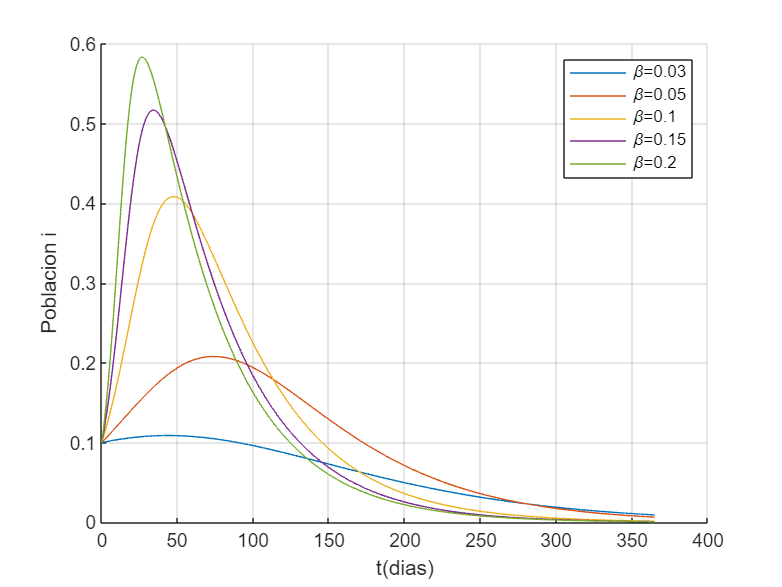

syms s(t) i(t) r(t) v(t)

%Parametros fijos
gamma = 0.02; delta = 0.001;

%Parametros variables
beta = [0.03 0.05 0.1 0.15 0.2];

%Ecuaciones
f3r = gamma*i;
f4v = delta*s;

%Metodo numerico
h = 0.1;
tmin = 0;
tmax = 365;
tspan = tmin:h:tmax;

%condiciones iniciales
CI = [0.8 0.1 0 0.1];

%Soli¿ucion metodo numerico
figure
for beta_i = beta
    f1s = -beta_i*s*i - delta*s;
    f2i = beta_i*s*i - gamma*i;
    f = odeFunction([f1s f2i f3r f4v],[s i r v]);
    [t,x]= ode45(f,tspan,CI);
    hold on
    grid on
    plot (t,x(:,2))
    
end
xlabel('t(dias)')
ylabel('Poblacion i')
legend({'\beta=0.03','\beta=0.05','\beta=0.1','\beta=0.15','\beta=0.2'})

La tasa de transmisión de un virus puede variar por distintos factores como las características del virus o por los cuidados  que se tengan entre humanos o la especie afectada, y dependiendo de esta tasa de transmisión se podrían controlar o evitar epidemias, en este caso específico se aprecia que con una tasa de transmisión menor a 0.03 se impediría el crecimiento del virus, evitando una propagación masiva.

#### 4

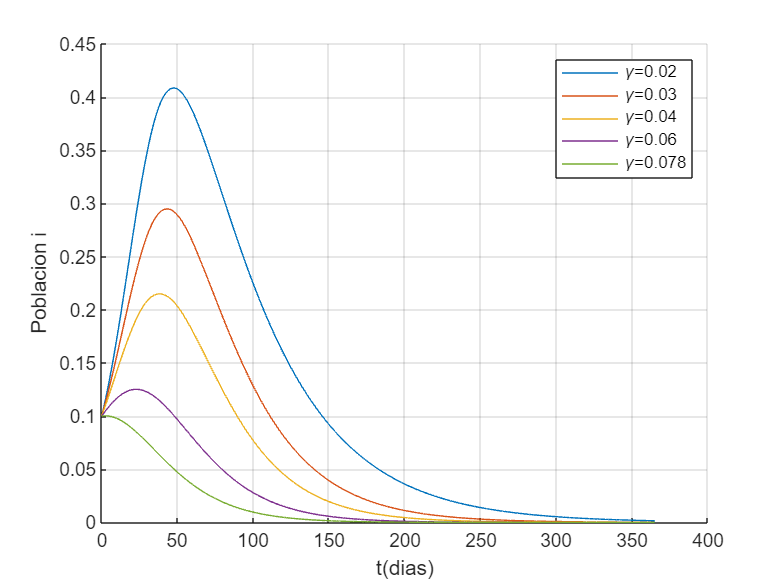

syms s(t) i(t) r(t) v(t)

%Parametros fijos
beta = 0.1;
delta = 0.001;

%Parametros variables
gamma = [0.02 0.03 0.04 0.06 0.078];

%Ecuaciones
f1s = -beta*s*i - delta*s;
f4v = delta*s;

%Metodo numerico
h = 0.1;
tmin = 0;
tmax = 365;
tspan = tmin:h:tmax;

%condiciones iniciales
CI = [0.8 0.1 0 0.1];

%Soli¿ucion metodo numerico
figure
for gamma_i = gamma
    f2i = beta*s*i - gamma_i*i;
    f3r = gamma_i*i;
    f = odeFunction([f1s f2i f3r f4v],[s i r v]);
    [t,x]= ode45(f,tspan,CI);
    hold on
    grid on
    plot (t,x(:,2))
    
end
xlabel('t(dias)')
ylabel('Poblacion i')
legend({'\gamma=0.02','\gamma=0.03','\gamma=0.04','\gamma=0.06','\gamma=0.078'})

La tasa de recuperación también puede variar por distintos factores, como lo puede ser el cuidado de la persona infectada o la resistencia del virus, y dependiendo de esto es que un virus puede convertirse o no en una epidemia, en este caso sé vario la tasa de recuperación hasta encontrar un valor con el cual el número de infectados iniciales no aumentara, hallando que con una tasa de recuperación de aproximadamente 0.078 se evitaría una epidemia, ya que el número de infectados tendería a bajar en todo momento.

5

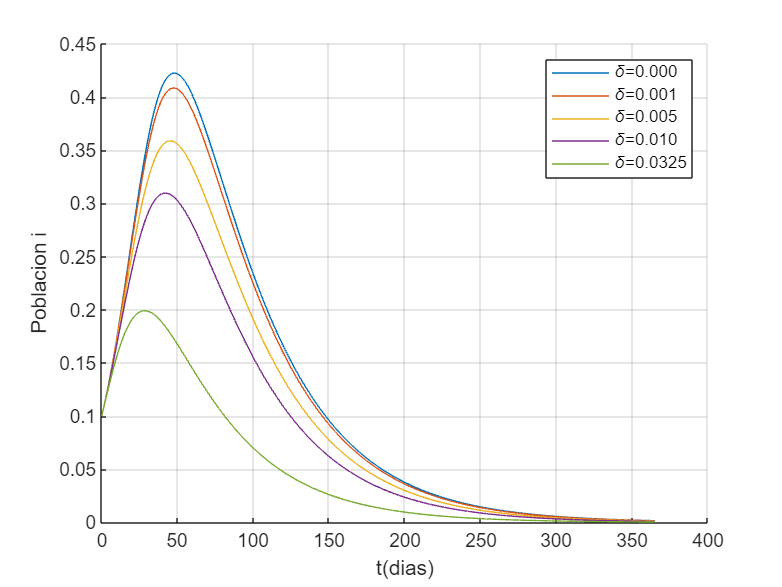

syms s(t) i(t) r(t) v(t)

%Parametros fijos
beta = 0.1;
gamma = 0.02;

%Parametros variables
delta = [0.0 0.001 0.005 0.01 0.0325];

%Ecuaciones
f2i = beta*s*i - gamma*i;
f3r = gamma*i;

%Metodo numerico
h = 0.1;
tmin = 0;
tmax = 365;
tspan = tmin:h:tmax;

%condiciones iniciales
CI = [0.8 0.1 0 0.1];

%Soli¿ucion metodo numerico
figure
for delta_i = delta
    f1s = -beta*s*i - delta_i*s;
    f4v = delta_i*s;
    f = odeFunction([f1s f2i f3r f4v],[s i r v]);
    [t,x]= ode45(f,tspan,CI);
    hold on
    grid on
    plot (t,x(:,2))
    
end
xlabel('t(dias)')
ylabel('Poblacion i')
legend({'\delta=0.000','\delta=0.001','\delta=0.005','\delta=0.010','\delta=0.0325'})

La tasa de vacunación depende únicamente de factores humanos, como la decisión que tiene cada individuo de vacunarse o no, o la capacidad que tienen los países o empresas para producir y suministrar las vacunas a la población, y dependiendo de cuál sea esta tasa de vacunación  e idealizando la eficiencia de la vacuna se puede predecir y controlar el comportamiento de un virus, evitando o dándole un mejor manejo a una epidemia. En el caso planteado, para lograr conseguir que la población infectada solo tuviera un crecimiento del 100% respecto a la población inicial infectada, es necesario que la tasa de vacunación sea de aproximadamente 0.0325.